## Video background subtraction

v = VideoReader('atrium.mp4');
background = rgb2gray(readFrame(v));
% imshow(background);

while hasFrame(v)
    frame = rgb2gray(readFrame(v));
    Dif = abs(frame - background) > 40;
%   D = (Dif(:,:,1) + Dif(:,:,2) + Dif(:,:,3)) > 0;
    imshow(Dif);
    drawnow
    background = 0.98 * background + 0.02*frame;
end

## Producte de convolució

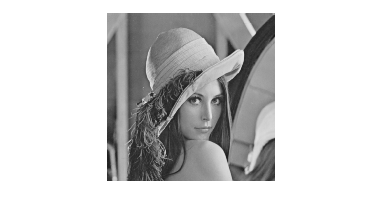

I = imread('lena_gray_512.tif');
% imshow(I);
h = [1 1 1; 1 6 1; 1 1 1]/14;
J = imfilter(I,h);
imshow(J);

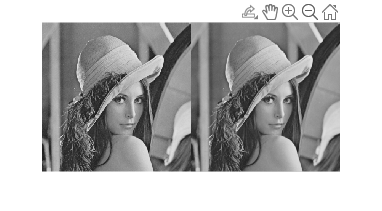

montage({I,J});